# Loads 2 different networks.

## This example contains: 

- Load 2 Input files. 

- Load networks. 

- Disp elevations for the two networks. 

- Set new elevations. 

- Disp new elevations. 

- Disp computed values for the two networks.

- Plot networks. 

- Unload libraries.

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load networks.

d1 = epanet('Net1.inp', 'ph'); 

Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


d2 = epanet('Net2.inp', 'ph');

Loading File "Net2.inp"...
Input File "Net2.inp" loaded successfully.


## Disp elevations for the two networks.

disp('Net1 - Elevations:')

Net1 - Elevations:


disp('--------------------')

--------------------


d1_Elevs = d1.getNodeElevations;
disp(d1_Elevs)

   710   710   700   695   700   695   690   700   710   800   850



disp('Net2 - Elevations:')

Net2 - Elevations:


disp('------------------')

------------------


d2_Elevs = d2.getNodeElevations;
disp(d2_Elevs)

    50   100    60    60   100   125   160   110   180   130   185   210   210   200   190   150   180   100   150   170   150   200   230   190   230   130   110   110   130   190   110   180   190   110   110   235



## Set new elevations.

disp('Net1 - New Elevations:'); 

Net1 - New Elevations:


disp('----------------------')

----------------------


d1.setNodeElevations(d1_Elevs + 200);
disp(d1.getNodeElevations)

         910         910         900         895         900         895         890         900         910        1000        1050



disp('Net2 - New Elevations:')

Net2 - New Elevations:


disp('----------------------')

----------------------


d2.setNodeElevations(d2_Elevs + 200);
disp(d2.getNodeElevations)

   250   300   260   260   300   325   360   310   380   330   385   410   410   400   390   350   380   300   350   370   350   400   430   390   430   330   310   310   330   390   310   380   390   310   310   435



## Disp computed values for the two networks.

disp('Net1 - Computed Time Series Values:')

Net1 - Computed Time Series Values:


disp('-----------------------------------')

-----------------------------------


disp(d1.getComputedTimeSeries)

              Time: [25×1 double]
          Pressure: [25×11 single]
            Demand: [25×11 single]
              Head: [25×11 single]
       NodeQuality: [25×11 single]
              Flow: [25×13 single]
          Velocity: [25×13 single]
          HeadLoss: [25×13 single]
            Status: [25×13 single]
           Setting: [25×13 single]
      ReactionRate: [25×13 single]
    FrictionFactor: [25×13 single]
       LinkQuality: [25×13 single]
      EnergyReport: [1×1 struct]
         StatusStr: {25×13 cell}



disp('Net2 - Computed Time Series Values:')

Net2 - Computed Time Series Values:


disp('-----------------------------------')

-----------------------------------


disp(d2.getComputedTimeSeries)

              Time: [56×1 double]
          Pressure: [56×36 single]
            Demand: [56×36 single]
              Head: [56×36 single]
       NodeQuality: [56×36 single]
              Flow: [56×40 single]
          Velocity: [56×40 single]
          HeadLoss: [56×40 single]
            Status: [56×40 single]
           Setting: [56×40 single]
      ReactionRate: [56×40 single]
    FrictionFactor: [56×40 single]
       LinkQuality: [56×40 single]
      EnergyReport: [1×1 struct]
         StatusStr: {56×40 cell}



## Plot networks.

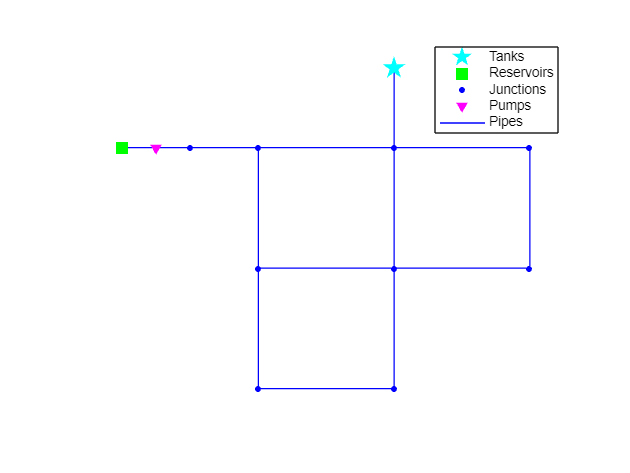

d1.plot;

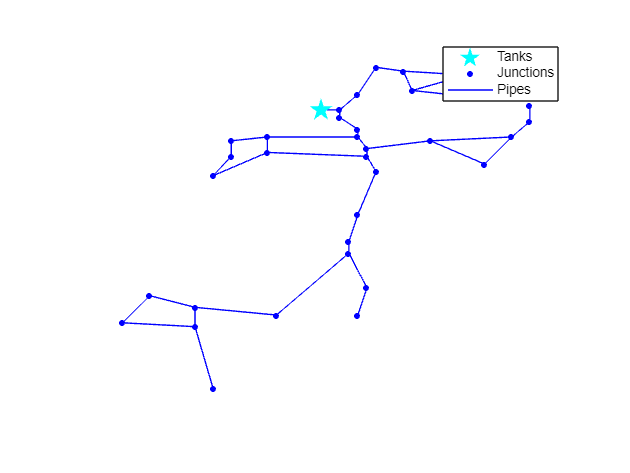

d2.plot;

## Unload libraries.

d1.unload;

EPANET Class is unloaded


d2.unload;

EPANET Class is unloaded
